% clearvars

trial = "20230906-104653"

trial = "20230906-104653"


file_405 = trial+"-405-Values.csv";
file_470 = trial+"-470-Values.csv";

% 使用csvread读取CSV文件内容
dat_405 = csvread(file_405);
dat_470 = csvread(file_470);

% 显示读取的矩阵内容
% disp(dat_405_value);


% 两通道可能差一张图
n_frame = min(size(dat_405),size(dat_470))

n_frame =    305     1


n_frame = n_frame(1)

n_frame = 305

% n_frame = 1200 

% x = dat_470(1:n_frame, 1); 
y_405 = dat_405(1:n_frame); 
y_470 = dat_470(1:n_frame); 

% 去掉一些串道之类的错误点
y_405 = denoise(y_405)

y_405 = 	1.0e+03 *

    2.6968
    2.6961
    2.7050
    2.7177
    2.7215
    2.7198
    2.7064
    2.6994
    2.6865
    2.6740


y_470 = denoise(y_470)

y_470 = 	1.0e+03 *

    6.7376
    6.7180
    6.7124
    6.7177
    6.6743
    6.6735
    6.6554
    6.6474
    6.6500
    6.6709



% 计算470和405的差值
y_470_405 = y_470 - y_405

y_470_405 = 	1.0e+03 *

    4.0408
    4.0219
    4.0074
    4.0000
    3.9528
    3.9537
    3.9490
    3.9480
    3.9635
    3.9969


y_470_405_scaled = y_470_405 - mean(y_470_405)

y_470_405_scaled =  -452.0229
 -470.8885
 -485.4296
 -492.7990
 -540.0712
 -539.1587
 -543.8711
 -544.8431
 -529.3577
 -495.9402


% 创建一个新的图像
fig = figure;

% 设置绘图区域在整个图片中的位置和边距
leftMargin = 0.06;
bottomMargin = 0.06;
width = 0.9;
height = 0.33; % 每个子绘图区域的高度占图片高度的比例
spacing = 0.07; % 两个子绘图区域之间的间距占图片高度的比例


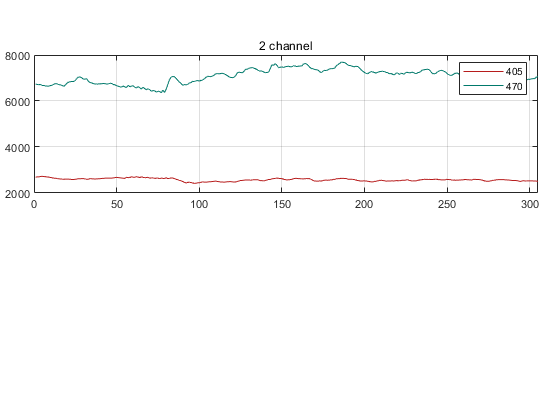

position1 = [leftMargin, bottomMargin+height+spacing+0.08, width, height];
subplot('Position', position1);

% 画双通道荧光值
plot(y_405,'-','Color','#b71c1c');
% plotOutliers(x_405, y_405)

hold on; 
plot(y_470, '-','Color','#00796b');
% plotOutliers(x_470, y_470)

ylabel('fluor value','FontSize', 15);
title('2 channel','FontSize', 15);
legend('405', '470'); 
grid on;
xlim([0, n_frame]);

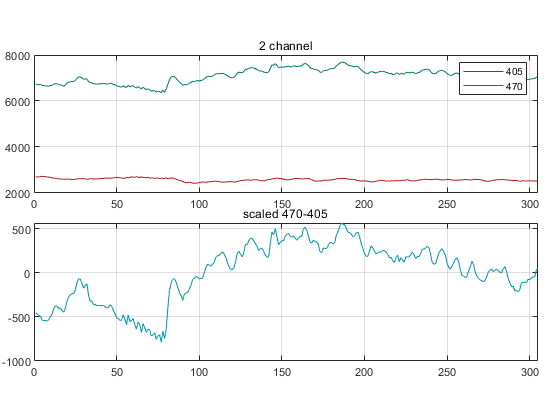

position2 = [leftMargin, bottomMargin+0.08, width, height];
subplot('Position', position2);

% 画470-405的荧光值
plot(y_470_405_scaled,'Color','#0097a7');
% plotOutliers(x_470,y_470_405_scaled)

ylabel('Δ fluor value','FontSize', 15);
title("scaled 470-405",'FontSize', 15); 
grid on;
xlim([0, n_frame]);

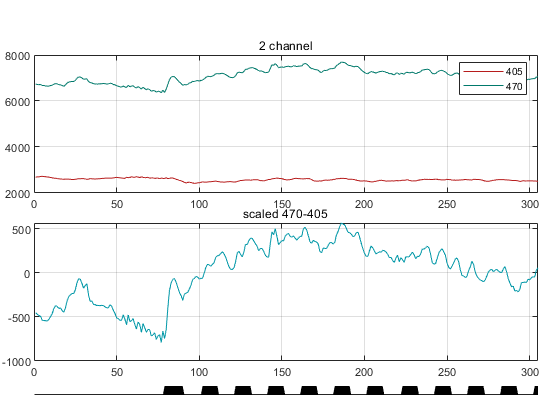

%% 读取刺激时间
stimfile = csvread("../raw/"+trial+".csv", 1, 0);

stim = zeros(n_frame, 1);
for i = 1:n_frame
    stim(i, 1) = stimfile((i-1)*20+1, 1 );
end

% 画出刺激时间
position3 = [leftMargin, bottomMargin, width, 0.02];
subplot('Position', position3);

% 使用 area 函数绘制区域图
area(stim, 'FaceColor', 'k', 'EdgeColor', 'none', 'LineStyle', 'none');
xlim([0, n_frame]);
axis off; % 不显示坐标轴

% text(0, 0.5, "stim", 'FontSize', 15, 'Rotation', 90, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');

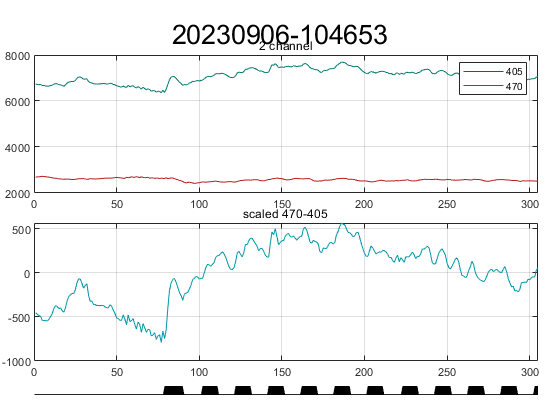

% 添加总标题
% title(trial,'FontSize', 15);
annotation('textbox', [0.45, 0.92, 0.1, 0.05], 'String', trial, 'HorizontalAlignment', 'center', 'FontSize', 20, 'EdgeColor', 'none');

% 'textbox' 参数指定了文本框的位置和大小，'String' 参数指定了标题的文本内容，'HorizontalAlignment' 参数设置标题在文本框中的水平对齐方式，'FontSize' 参数设置标题的字体大小，'EdgeColor' 参数设置文本框的边框颜色。

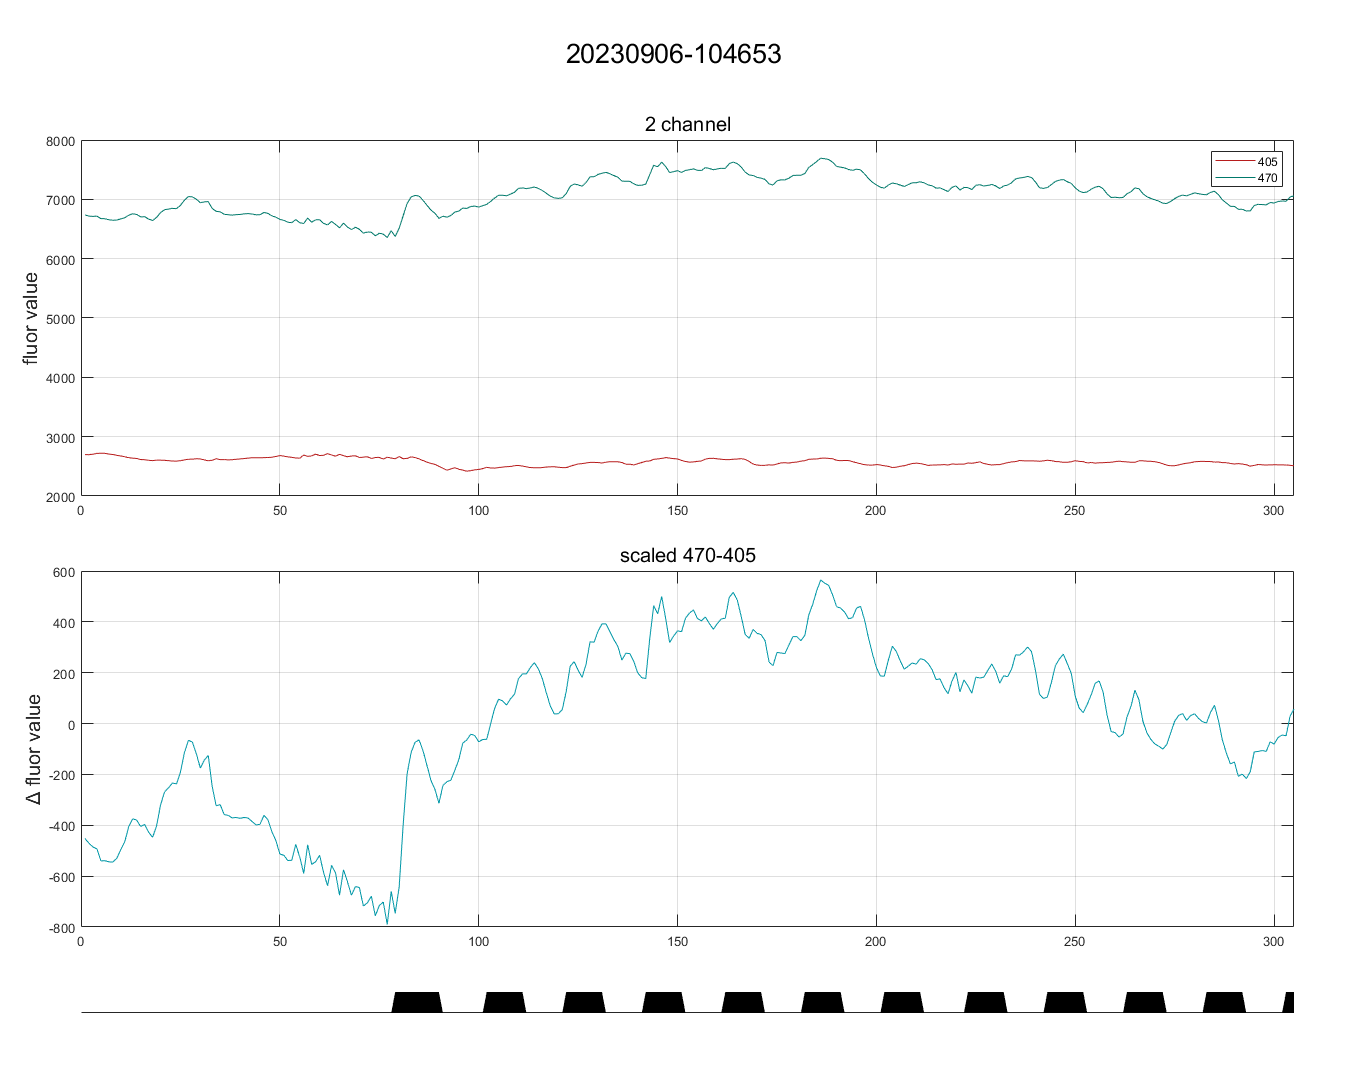

% 调整图像尺寸
%fig = gcf;
newWidth = 2000;
newHeight = 1600;
set(fig, 'Position', [0, 0, newWidth, newHeight]);

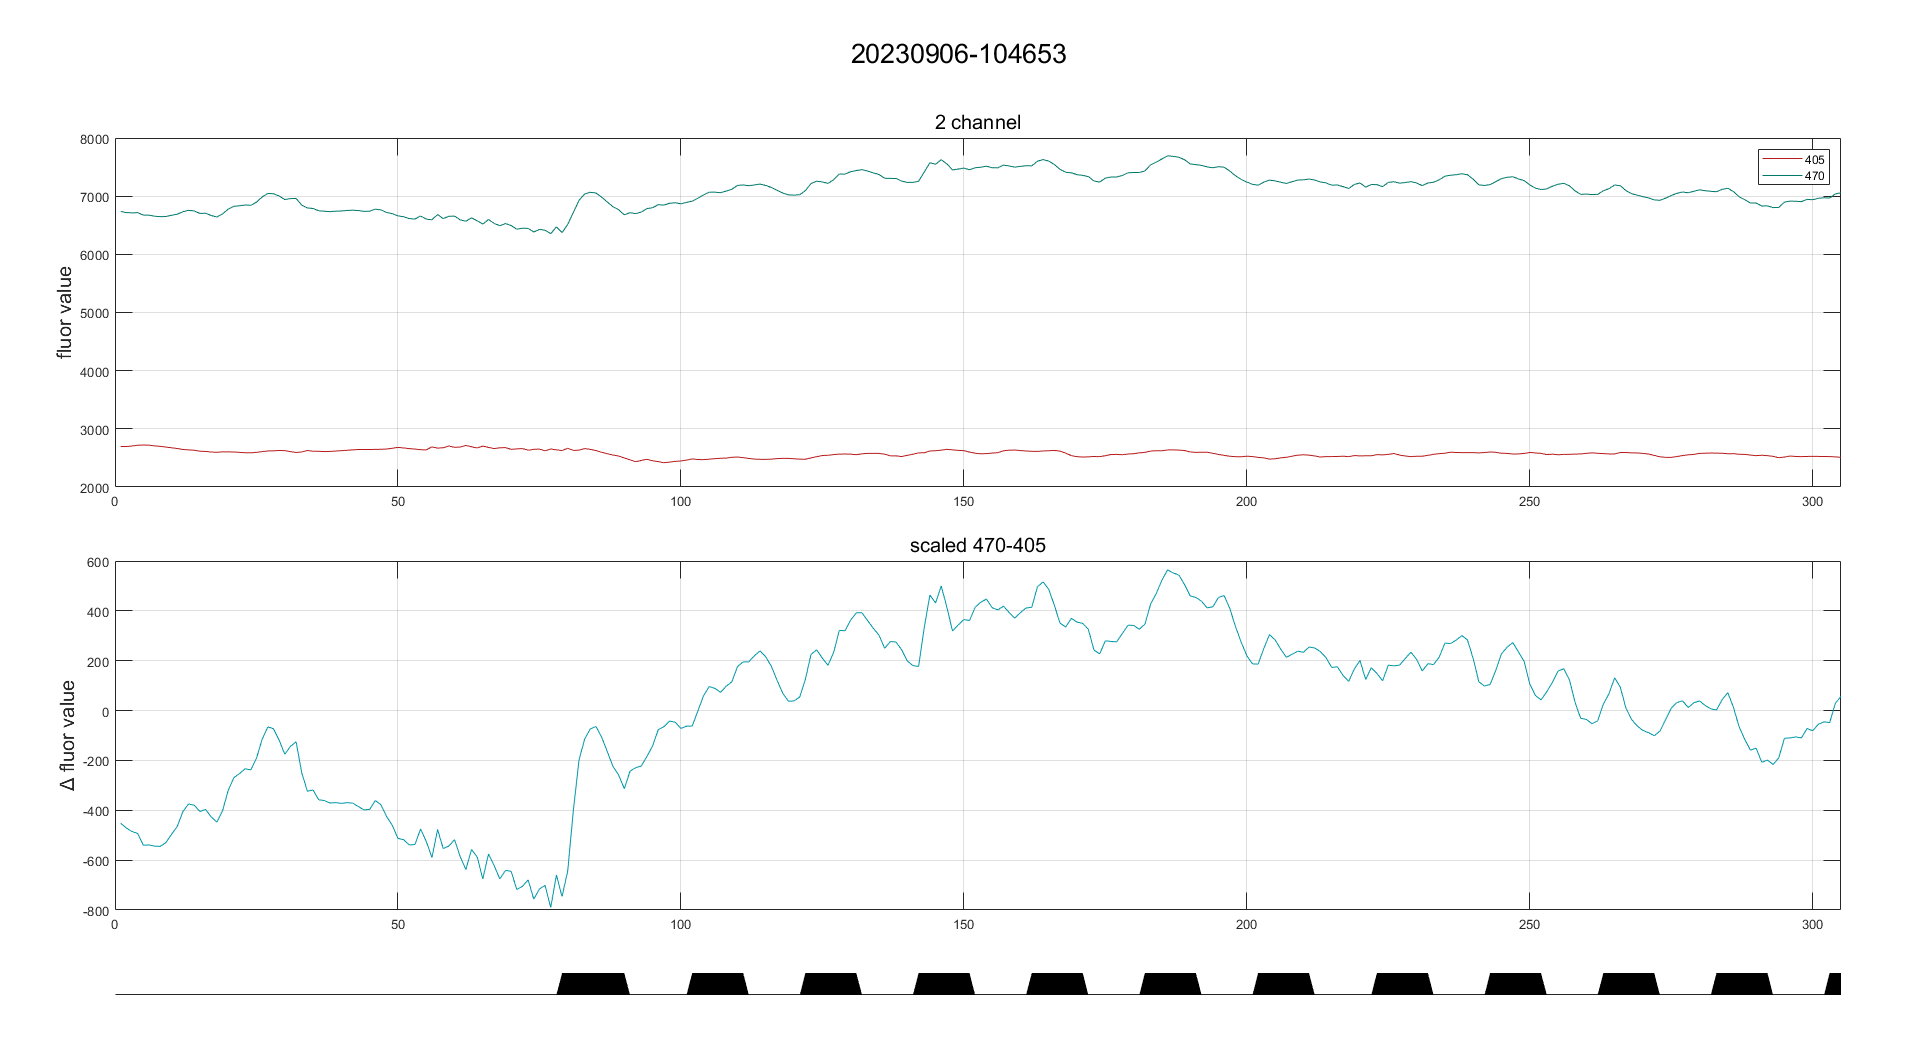

% 保存图像为PNG格式
outputFileName = trial+"_value_stimu";
saveas(fig, outputFileName, 'png');